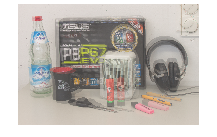

%% Load images
Image1 = imread('sceneL.png');
IGray1 = rgb_to_gray(Image1);
Image2 = imread('sceneR.png');
IGray2 = rgb_to_gray(Image2);

%% Calculate Harris features
features1 = harris_detector(IGray1,'segment_length',9, ...
    'k',0.05,'min_dist',40,'N',50,'do_plot',false);
features2 = harris_detector(IGray2,'segment_length',9, ...
    'k',0.05,'min_dist',40,'N',50,'do_plot',false);

%% Correspondence estimation
correspondences = point_correspondence(IGray1,IGray2, ...
    features1,features2,'window_length',25,'min_corr',0.9,'do_plot',false);

%% Determine robust corresponding image points with the RANSAC algorithm
[correspondences_robust, largest_set_F] =  ...
    F_ransac(correspondences, 'tolerance', 0.04);

%% Visualize robust corresponding image points
figure(1)
imshow(Image1);
hold on
imshow(Image2);
hold on
alpha(0.5);  % add transparancy of 50%

for i=1:size(correspondences_robust,2)
    plot(correspondences_robust(1,:), correspondences_robust(2,:), ...
        'r*', 'MarkerSize', 6, 'LineWidth',1);
    plot(correspondences_robust(3,:), correspondences_robust(4,:), ...
        'b*', 'MarkerSize', 6, 'LineWidth',1);
    plot([correspondences_robust(1,i),correspondences_robust(3,i)], ...
        [correspondences_robust(2,i),correspondences_robust(4,i)], 'g-', 'LineWidth',1);
    hold on
end

%% Calculate essential matrix
% load('K.mat');
E = epa(correspondences_robust);
disp(E);

     0     0     0
     0     0     0
     0     0     1




[T1, R1, T2, R2, ~, ~] = TR_from_E(E)

U =      0     0     1
     0     1     0
     1     0     0


Delta =      1     0     0
     0     0     0
     0     0     0


V =      0     0     1
     0     1     0
     1     0     0


T1 =      0     0     0
     0     0     1
     0     0     0


R1 =      1     0     0
     0     0    -1
     0     1     0


T2 =      0     0     0
     0     0    -1
     0     0     0


R2 =      1     0     0
     0     0     1
     0    -1     0
